# Module 2 Video 1

## Working with Video Files

v = VideoReader("liquidVideo.mp4")

v =   VideoReader with properties:

   General Properties:
            Name: 'liquidVideo.mp4'
            Path: 'D:\Mina\Document\Coursera\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   Video Properties:
           Width: 120
          Height: 216
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



% vOut = VideoWriter("liquidVideoBinary.mp4", "MPEG-4")
% vOut.FramRate = v.FrameRate;

nFrames = v.NumFrames;
% open(vOut)

liquidPart = [];
emptyPart = [];

for i = 1:nFrames
    img = read(v, i);
    
    bw = liquidMask(img);

    liquidPart = [liquidPart; sum(~bw(:))];
    emptyPart = [emptyPart, sum(bw(:))];

    % frame = imfuse(img, bw, "montage");
    % writeVideo(vOut, frame);

    time = v.CurrentTime;

end
% close(vOut)
v.CurrentTime = 0;


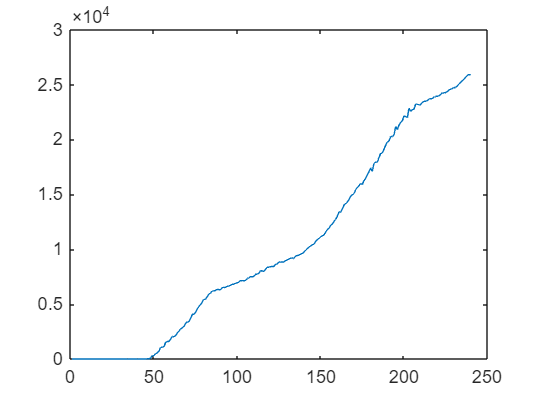

plot(liquidPart)

function [BW,maskedRGBImage] = liquidMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 11-Aug-2024
%------------------------------------------------------


% Convert RGB image to chosen color space
I = RGB;

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 90.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 255.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 89.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Invert mask
BW = ~BW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
